#### Loading the Trained Random Forest Model

predRFLoad=load('finalModelRF.mat')

predRFLoad = struct with fields:
           XTest: [1527×42 table]
    finalModelRF: [1×1 classreg.learning.classif.ClassificationBaggedEnsemble]
           yTest: [1527×1 table]


predRF= predict(predRFLoad.finalModelRF,predRFLoad.XTest)

predRF =      0
     0
     0
     0
     0
     0
     1
     0
     0
     0


#### Plotting Confusion Matrix

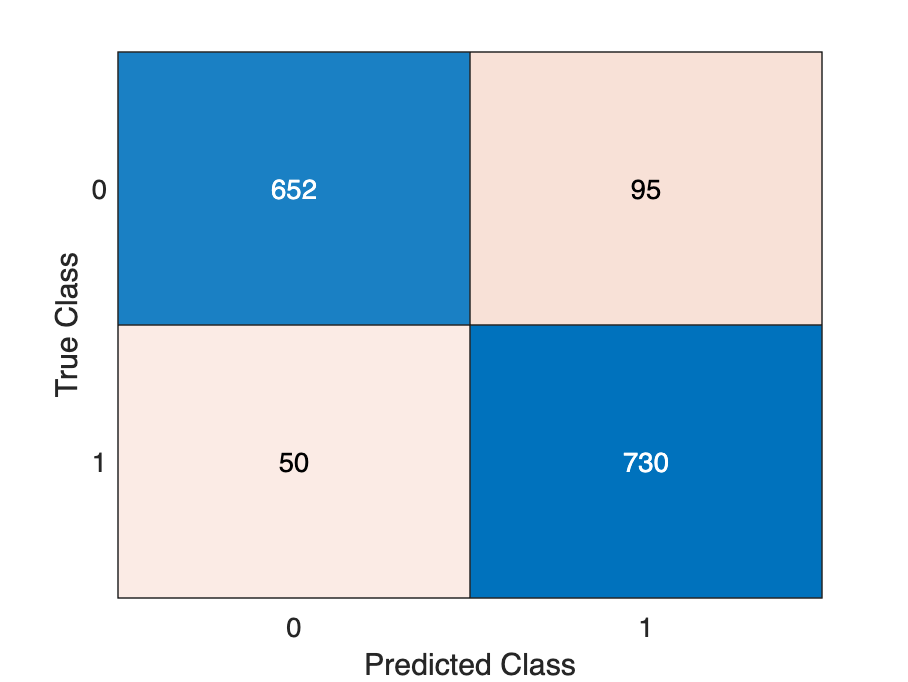

cm = confusionchart(table2array(predRFLoad.yTest),predRF);

#### Precision

cmatrixRF= confusionmat(table2array(predRFLoad.yTest),predRF) 

cmatrixRF =    652    95
    50   730



precisionRF =  diag(cmatrixRF)./sum(cmatrixRF,2)

precisionRF =     0.8728
    0.9359


overAllPrecRF= mean(precisionRF)

overAllPrecRF = 0.9044

#### Recall


recallRF =  diag(cmatrixRF)./sum(cmatrixRF,1)';
overAllRecRF= mean(recallRF)

overAllRecRF = 0.9068

#### F1 Score

f1ScoreRF = 2*(overAllPrecRF.*overAllRecRF)./(overAllPrecRF+overAllRecRF)

f1ScoreRF = 0.9056

[~,Scores] = predict(predRFLoad.finalModelRF,predRFLoad.XTest)

Scores =     0.9996    0.0004
    0.9996    0.0004
    0.7765    0.2235
    0.9988    0.0012
    0.9988    0.0012
    0.9739    0.0261
    0.0724    0.9276
    0.9997    0.0003
    0.9903    0.0097
    0.5630    0.4370


classNamesBankData=predRFLoad.finalModelRF.ClassNames

classNamesBankData =      0
     1


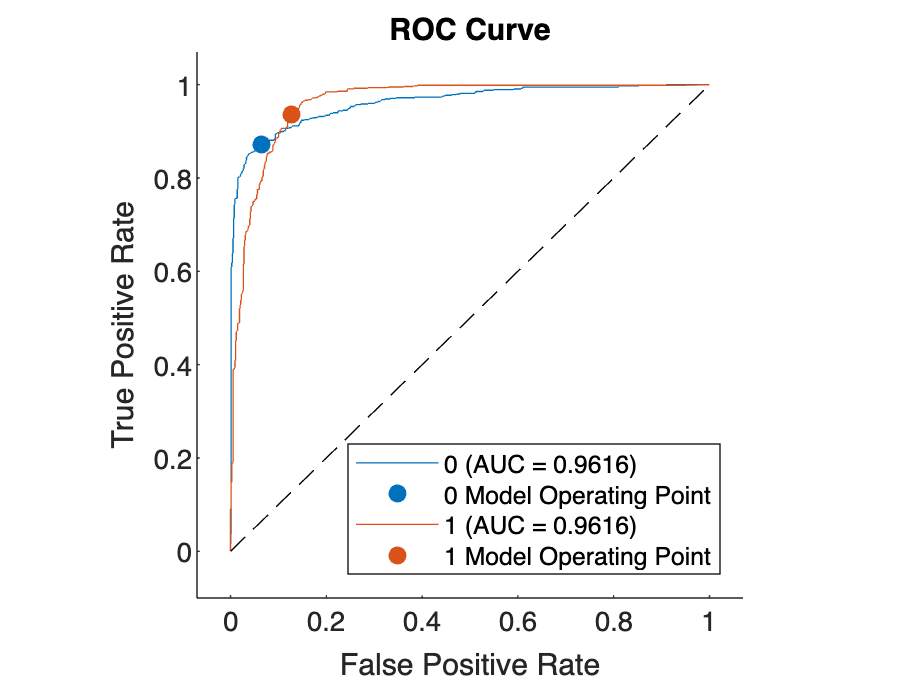


rocObj = rocmetrics(table2array(predRFLoad.yTest),Scores,classNamesBankData);
plot(rocObj)